# Homework 3: Fourier, Sobel, Transformations, and Registration

#### Name: Grant Roberts

#### Due: 03/24/2020

#### BMI/CS 567: Medical Image Analysis 

## **3.1     Fourier & Sobel**

**In the first section of this homework you will learn about the Sobel filter and investigate some Fourier transform properties. In this section you may use Matlab built-in functions.**

**(a) The Sobel filter approximates the gradient of an image using a pair of 3 x 3 kernel filters:**


$${\mathrm{K}}_x \;\;=\;\left\lbrack \begin{array}{ccc}
-1 & 0 & 1\\
-2 & 0 & 2\\
-1 & 0 & 1
\end{array}\right\rbrack ,\;\;\;\;\;\;\;\;\;\;\;\;{\mathrm{K}}_y =\left\lbrack \begin{array}{ccc}
1 & 2 & 1\\
0 & 0 & 0\\
-1 & -2 & -1
\end{array}\right\rbrack$$


${\mathrm{K}}_x$** estimates the gradient in the horizontal direction, and **${\mathrm{K}}_y$** estimates the gradient in the vertical direction. The magnitude of the overall gradient is the sum of both. This is a very popular edge detection filter. Load the **`liver.jpeg`** image from the course website. Use **`subplot`** to display:**

- **The original image **$\mathrm{X}$

clean
x = imread('liver.jpeg');
x = [zeros(107,339);x;zeros(110,339)];
x = [zeros(512,85),x,zeros(512,88)];
figure; subplot(2,2,1); imshow(x,[]); title('Zero Padded Image')

- **The result of convolving **$\mathrm{X}$** with **${\mathrm{K}}_x$**, i.e., **${\mathrm{X}*\mathrm{K}}_x$

kx = [-1 0 1; -2 0 2; -1 0 1];
x_kx = conv2(kx,x);
subplot(2,2,2); imshow(x_kx,[]); title('Image Convolved with kx');

- **The result of convolving **$\mathrm{X}$** with **${\mathrm{K}}_y$**, i.e., **${\mathrm{X}*\mathrm{K}}_y$

ky = [1 2 1;0 0 0;-1 -2 -1];
x_ky = conv2(ky,x);
subplot(2,2,3); imshow(x_ky,[]), title('Image Convolved with ky');

- **The sum of both convolutions, i.e., **${\mathrm{X}*\mathrm{K}}_x$** + **${\mathrm{X}*\mathrm{K}}_y$**.**

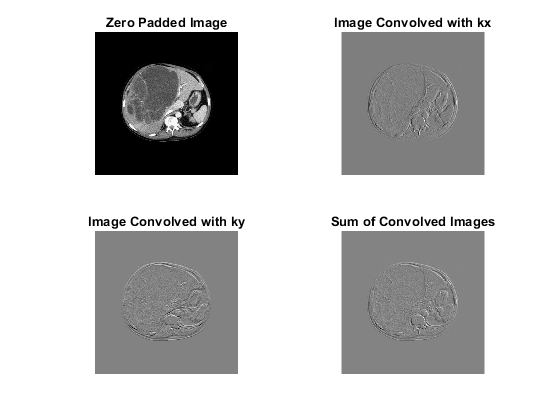

x_sum = x_kx + x_ky;
subplot(2,2,4); imshow(x_sum,[]); title('Sum of Convolved Images');

**(b)  Use **`subplot`** to display the original Image **$\mathrm{X}$ **and its Fourier transform, with lower frequencies at the center, and properly log-scaled.**

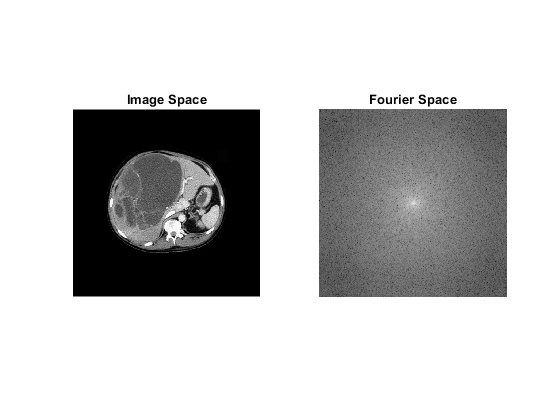

X = fft2c(x);
figure; subplot(1,2,1); imshow(x,[]); title('Image Space')
subplot(1,2,2); imshow(log(abs(X)),[]); title('Fourier Space')

**(c) We will now study the effect of convolution in the Fourier domain. Letting **$\hat{\mathrm{X}}$**, **${\hat{\mathrm{K}} }_x$**, **${\hat{\mathrm{K}} }_y$** be the Fourier transforms of **$\hat{\mathrm{X}}$**, **${\mathrm{K}}_x$**, **${\mathrm{K}}_y$** (properly padded with zeros), compute and display (using **`subplot`**):**

- 
$$\hat{\mathrm{X}} \odot {\hat{\mathrm{K}} }_x$$


kx_pad = padarray(kx,[1 1],'pre'); % Add an extra row
kx_pad = padarray(kx_pad,[254 254]); % Pad with zeros to match size of X
KX = fft2c(kx_pad);
X_KX = X.*KX;
figure; subplot(1,3,1); imshow(X_KX,[]); title('Kx Filtering in Fourier Space')

- 
$$\hat{\mathrm{X}} \odot {\hat{\mathrm{K}} }_y$$


ky_pad = padarray(ky,[1 1],'pre');
ky_pad = padarray(ky_pad,[254 254]);
KY = fft2c(ky_pad);
X_KY = X.*KY;
subplot(1,3,2); imshow(X_KY,[]); title('Ky Filtering in Fourier Space')

- $\hat{\mathrm{X}} \odot {\hat{\mathrm{K}} }_x$ + $\hat{\mathrm{X}} \odot {\hat{\mathrm{K}} }_y$

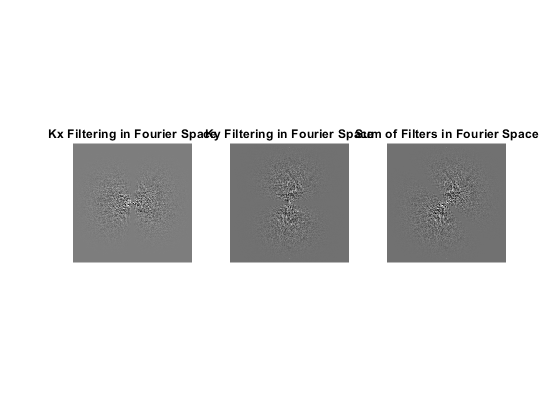

X_SUM = X_KX + X_KY;
subplot(1,3,3); imshow(X_SUM,[]); title('Sum of Filters in Fourier Space')

**Is there some pattern that you can recognize? E.g., do **${\mathrm{K}}_x$** and **${\mathrm{K}}_y$** behave like low-pass or high-pass filters?**

It appears that multiplying Kx times the image in the Fourier Domain looks similar to the process of convolving kx with the image in image space. Particularly, it looks like k-space appears to be 'edge filtered' in the respective directions of the filters. 

**(d) Compute and display (using **`subplot`**) the inverse Fourier transform of the matrices in (c). How do these compare with the direct convolutions from (a)?**

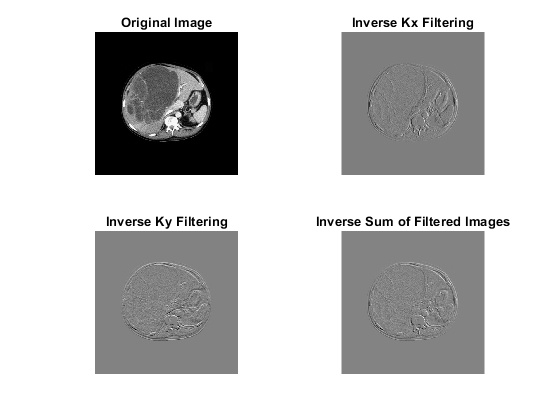

figure; subplot(2,2,1); imshow(ifft2c(X),[]); title('Original Image')
subplot(2,2,2); imshow(ifft2c(X_KX),[]); title('Inverse Kx Filtering')
subplot(2,2,3); imshow(ifft2c(X_KY),[]); title('Inverse Ky Filtering')
subplot(2,2,4); imshow(ifft2c(X_SUM),[]); title('Inverse Sum of Filtered Images')

## **3.2     Spatial Transformations & Landmark Registration**

**In this section you will implement some basic spatial image transformations (translations, rotations, and scalings), and align two images using Landmark registration. In this section you may use any interpolation method you want.**

**(e) Create your own function to translate an image.**

See `translate below `in 'Custom Functions'

**(f) Create your own function to rotate an image.**

See rotate` below `in 'Custom Functions'

**(g) Create your own function to scale an image.**

See scale` below `in 'Custom Functions'

**(h) Load the **`liver.jpeg`** image from the course website. Using your functions from above, rotate it **${40}^{\circ }$**, translate it (30, 20) pixels, and scale it by 1.5. Use **`subplot`** to display the original image **$\mathrm{X}$** and the transformed image **${\mathrm{X}}_T$** at each stage, for all the possible transformation orders. Are they the same?**

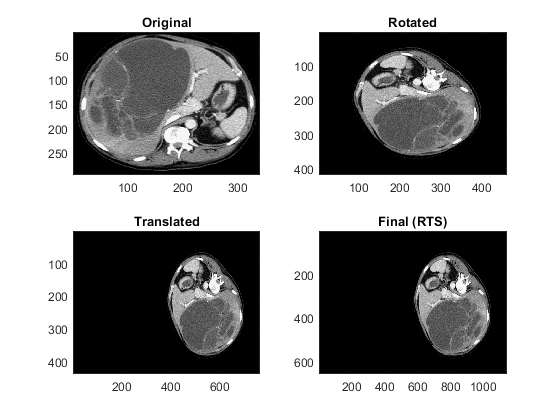

image = imread('liver.jpeg');
figure; subplot(2,2,1); imagesc(image); colormap('gray'); title('Original');
image_rotate = Rotate(image,40);
subplot(2,2,2); imagesc(image_rotate); title('Rotated');
image_trans = Translate(image_rotate,30,20);
subplot(2,2,3); imagesc(image_trans); title('Translated');
image_scale = Scale(image_trans,1.5);
subplot(2,2,4); imagesc(image_scale); title('Final (RTS)')

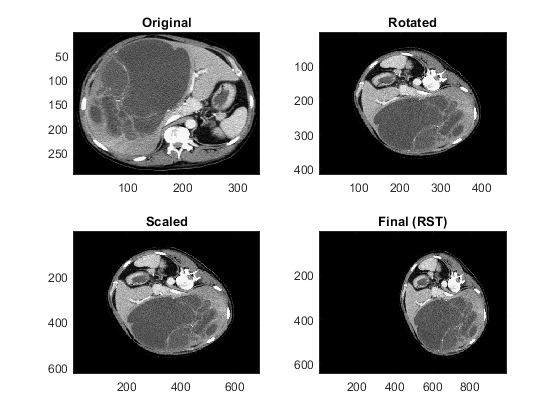


figure; subplot(2,2,1); imagesc(image); colormap('gray'); title('Original');
image_rotate = Rotate(image,40);
subplot(2,2,2); imagesc(image_rotate); title('Rotated');
image_scale = Scale(image_rotate,1.5);
subplot(2,2,3); imagesc(image_scale); title('Scaled');
image_trans = Translate(image_scale,30,20);
subplot(2,2,4); imagesc(image_trans); title('Final (RST)')

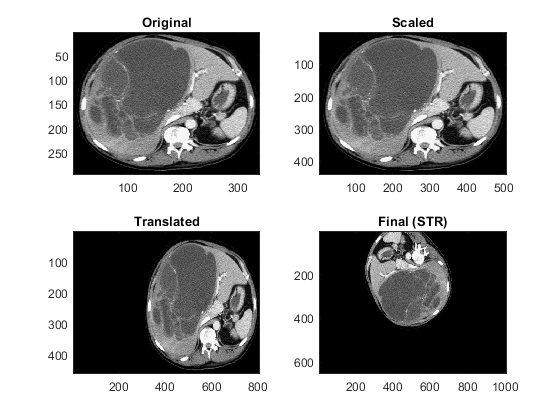


figure; subplot(2,2,1); imagesc(image); colormap('gray'); title('Original');
image_scale = Scale(image,1.5);
subplot(2,2,2); imagesc(image_scale); title('Scaled');
image_trans = Translate(image_scale,30,20);
subplot(2,2,3); imagesc(image_trans); title('Translated');
image_rotate = Rotate(image_trans,40);
subplot(2,2,4); imagesc(image_rotate); title('Final (STR)')

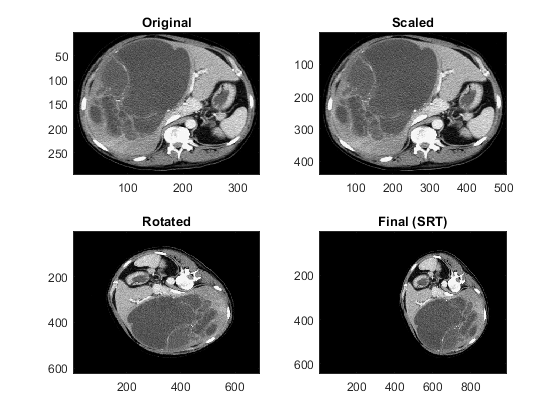


figure; subplot(2,2,1); imagesc(image); colormap('gray'); title('Original');
image_scale = Scale(image,1.5);
subplot(2,2,2); imagesc(image_scale); title('Scaled');
image_rotate = Rotate(image_scale,40);
subplot(2,2,3); imagesc(image_rotate); title('Rotated');
image_trans = Translate(image_rotate,30,20);
subplot(2,2,4); imagesc(image_trans); title('Final (SRT)')

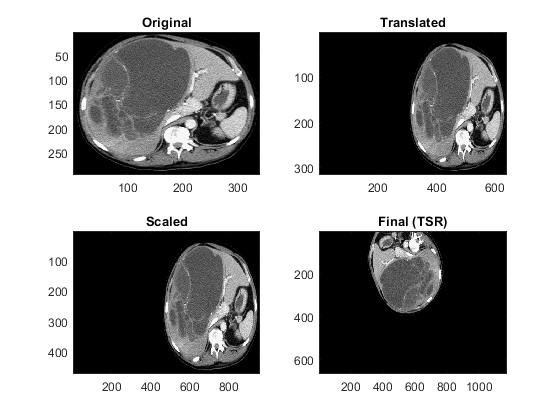




figure; subplot(2,2,1); imagesc(image); colormap('gray'); title('Original');
image_trans = Translate(image,30,20);
subplot(2,2,2); imagesc(image_trans); title('Translated');
image_scale = Scale(image_trans,1.5);
subplot(2,2,3); imagesc(image_scale); title('Scaled');
image_rotate = Rotate(image_scale,40);
subplot(2,2,4); imagesc(image_rotate); title('Final (TSR)')

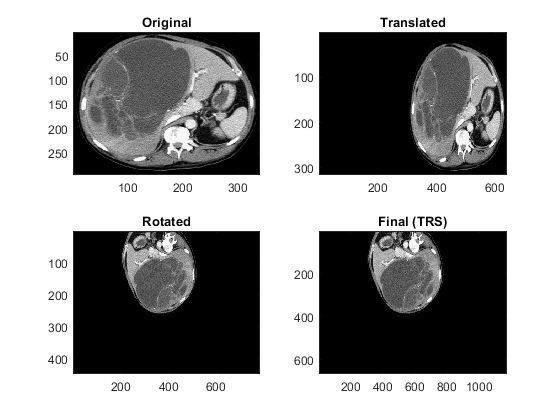


figure; subplot(2,2,1); imagesc(image); colormap('gray'); title('Original');
image_trans = Translate(image,30,20);
subplot(2,2,2); imagesc(image_trans); title('Translated');
image_rotate = Rotate(image_trans,40);
subplot(2,2,3); imagesc(image_rotate); title('Rotated');
image_scale = Scale(image_rotate,1.5);
subplot(2,2,4); imagesc(image_scale); title('Final (TRS)')

**(i) To perform Landmark registration, select K = 10 reference points (**$x_k$,$y_k$**) in **$\mathrm{X}$**, and their corresponding points (**${x_k }^{\prime }$,${y_k }^{\prime }$**) in **${\mathrm{X}}_T$** . *****Hint: Determining such points should be easy, as you had control over the spatial transformation*****. Use these points to identify the mapping matrix **$\mathrm{M}$** that aligns **${\mathrm{X}}_T$** with **$\mathrm{X}$**. What do you obtain for **$\mathrm{M}$**?**

**(j) Create a function that applies a mapping **$\mathrm{M}$** to an image. Use **`subplot`** to display **${\mathrm{X}}_T$** and the result of applying the mapping **$\mathrm{M}$** you obtained above to **${\mathrm{X}}_T$** . Is it the same as **$\mathrm{X}$**?**

**(k) What happens if instead of K = 10 you use K = 5, 3, 2, 1 reference points? What conclusions can you draw from this?**

### Custom Functions

#### *Corrected Fourier Transform (with shifts)*

function transf = fft2c(x)
    transf = 1/sqrt(length(x(:)))*fftshift(fft2(ifftshift(x)));
end 


#### *Corrected Inverse Fourier Transform (with shifts)*

function transf = ifft2c(x)
    transf = sqrt(length(x(:)))*ifftshift(ifft2(fftshift(x)));
end 

#### *Translate*

function translated = Translate(image,deltaX,deltaY)
    T = [1 0 deltaY; 0 1 deltaX; 0 0 1];
    for i = 1:size(image,1)
        for j = 1:size(image,2)
            coords = T*[i;j;1];
            coords = round(coords);
            translated(coords(1),coords(2)) = image(i,j);
        end
    end
end 

#### *Rotate*

function rotated = Rotate(image,theta)
    [x,y] = size(image);
    R = [cos(theta) sin(theta) x/2; -sin(theta) cos(theta) y/2; 0 0 1];    
    xx = x*sqrt(2);
    yy = y*sqrt(2);
    for t=1:xx
        for s=1:yy
            coords = uint16(R*[t-xx/2;s-yy/2;1]);
            i = coords(1);
            j = coords(2);
            if i>0 && j>0 && i<=x && j<=y           
               rotated(t,s,:)=image(i,j,:);
            end
        end
    end
end 

#### *Scale*

function scaled = Scale(image,scale)
    % nearest neighbor interpolation
    numRows = size(image,1);
    numCols = size(image,2);
    rowInds = round( (1:(numRows*scale))./scale );
    colInds = round( (1:(numCols*scale))./scale );
    scaled = image(rowInds,colInds);
end 